clc
clear all
close all
rng(0)
save_run = false;
rand_init = randn(9, 1)*0.01*0;
rand_init = rand_init - mean(rand_init);
rand_init = rand_init + 1;

# M3C Simulation

## Parameters

Simulation and control steps

%% Simulation
Tf = 0.5;                      % Time length
Ts = 2e-5;	                 % Sample time
Ns = round(Tf/Ts + 1);       % Number of steps
Tsim = linspace(0, Tf, Ns);
%% Total energy balance
Ti = 2e-4;                   % Sample time
Ni = round(Tf/Ti + 1);       % Number of steps
Tcur = linspace(0, Tf, Ni);
%% ICB + LFOM
Tl = 1e-4;                   % Sample time
Nl = round(Tf/Tl + 1);       % Number of steps
lmax = 10;                   % BCD solver max iterations
Ten = linspace(0, Tf, Nl);
% Prediction horizon
Np = 2;
tp = linspace(0, Np*Tl, Np);

Input grid voltage

Ax = 5000;
fx = 50;
wx = 2*pi*fx;

Output grid voltage

Ay = 7000;
fy = 50;
wy = 2*pi*fy;

Converter model

% M3C incidence matrix
A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m = size(A, 2);
N = null(A, 'rational');
% N = [-0.4430   -0.4780    0.0994    0.0994
%       0.3611    0.0175   -0.5599    0.0175
%       0.0819    0.4605    0.4605   -0.1169
%       0.6051   -0.0137    0.1976    0.1976
%      -0.4933    0.3094    0.0981    0.3094
%      -0.1118   -0.2957   -0.2957   -0.5070
%      -0.1621    0.4917   -0.2970   -0.2970
%       0.1322   -0.3269    0.4617   -0.3269
%       0.0300   -0.1648   -0.1648    0.6239];
N1 = repmat({N}, 1, Np);
N1 = blkdiag(N1{:});
C = 20e-3;			     % Average cluster capacitance
L = 200e-4;              % Branch inductance
R = 0.001;			     % Branch resistance
% Current discrete model
Ad = expm(-Tl*R/L*eye(m));
Bd = (-R/L*eye(m))\(Ad-eye(m))*(-eye(m)/L);

## Supervised leaning control of M3C

Train NN to imitate ICB and LFOM control (generate circulating currents and common model voltage references).

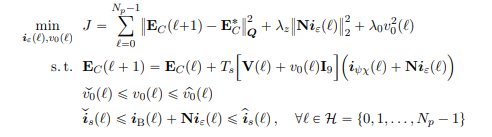

#### Gather data

                                          %% Name                            %% Location            %% Description
% External variables
Vxy_cell = num2cell(zeros(6, Nl), 1);     % External phase voltages          | Input/output ports   | Measured
Von_cell = num2cell(zeros(1, Nl), 1);     % Common mode voltage              | Between input/output | Applied (through Vs)
Ixy_cell = num2cell(zeros(6, Nl), 1);     % External currents                | Input/output ports   | Measured
Ixy_ref_cell = num2cell(zeros(6, Nl), 1); % Input/output currents references | Input/output ports   | Calculated in Total Energy Balance and Output System Control

% Cluster/Branch variables
Ec_ref_cell = num2cell(zeros(1, Nl), 1);  % Energy reference                 | Clusters             | Calculated: mean(Ec)
Ec_cell = num2cell(zeros(m, Nl), 1);      % Energy                           | Clusters             | Calculated: 0.5*c*v^2
Ec_pred_cell = num2cell(zeros(m, Nl), 1); % Predicted energy (t+1)           | Clusters             | Calculated: Prediction

Vs_cell = num2cell(zeros(m, Nl), 1);      % Voltages (control action)        | Clusters             | Applied (Modulated)
VB_cell = num2cell(zeros(m, Nl), 1);      % "Basic" voltages                 | Branchs              | Calculated: VB = A'*Vxy

Is_cell = num2cell(zeros(m, Nl), 1);      % Currents                         | Clusters             | Measured
IB_cell = num2cell(zeros(m, Nl), 1);      % Basic currents                   | Clusters             | Calculated: pinv(A)*Ixy
Iz_cell = num2cell(zeros(m, Nl), 1);      % Circulating currents             | Clusters             | Calculated: Is-IB
Ie_cell = num2cell(zeros(4, Nl), 1);      % Internal LI currents             | Nowhere (Clusters)   | Calculated: pinv(N)*Iz

Is_ref_cell = num2cell(zeros(m, Nl), 1);  % Currents references              | Clusters             | Measured
IB_ref_cell = num2cell(zeros(m, Nl), 1);  % Basic currents references        | Clusters             | Calculated: pinv(A)*Ixy_ref
Iz_ref_cell = num2cell(zeros(m, Nl), 1);  % Circulating currents references  | Clusters             | Calculated: Is_ref-IB_ref
Ie_ref_cell = num2cell(zeros(4, Nl), 1);  % Internal LI currents references  | Nowhere (Clusters)   | Applied

% Ec_cell
% Ec_ref_cell
% Vxy_cell
% V_cell
% Ixy_cell
% IB_cell
% Ixy_ref_cell
% IB_ref_cell
% Vs_cell
% Is_cell
% Ie_cell
% Von_cell
% Ec_pred_cell

% xseq = zeros(Nwindow, Ninputs);

## Simulation

Reference frame transformations

Tabc_ab = (2/3)*[1, -1/2, -1/2; 0, sqrt(3)/2, -sqrt(3)/2];
Tab_abc = [1, 0; -1/2, sqrt(3)/2; -1/2, -sqrt(3)/2];

Tabc_dq_function = @(g) (2/3)*[cos(g), cos(g-2*pi/3), cos(g+2*pi/3); -sin(g), -sin(g-2*pi/3), -sin(g+2*pi/3)];

Limit values

Vxy_max = Ax+Ay;     % Branch voltage
Von_max = Vxy_max/2; % Common mode voltage
Is_max = 250;        % Cluster current
Ix_max = 200;        % Input current

Constant references

%% Cluster capacitor voltage reference
% Vc0 = 1.4815*Vxymax; % Initial cluster capacitor voltage
Vc0 = 1.5*Vxy_max;
% vc_ref = 1.49*Vxymax;
vc_ref = Vc0;

Control parameters and initialization

- PLL

% Parameters
Kp_pll = 0.5; Ki_pll = 1.5; n_pll = 1-Ti*0.5*Ki_pll/Kp_pll;
% Initialization
[ax_pll, ux_pll, ay_pll, uy_pll] = deal(0);
[wx_pll, wy_pll, vxd_pll, vxq_pll, vyd_pll, vyq_pll] = deal(zeros(1, Ns));
[gx_pll, gy_pll] = deal(zeros(1, Ns+1));

- TEB

% Parameters
Kp_teb = 6.48156886919677*3;
Ki_teb = 397.264633627808/20;
n_teb = 1-Ti*0.5*Ki_teb/Kp_teb;
% Initialization
[a_teb, u_teb] = deal(0);
[Ixd_ref, Ixq_ref] = deal(zeros(1, Ns));
[ixa_ref, ixb_ref, ixc_ref, iyr_ref, iys_ref, iyt_ref] = deal(zeros(1, Ns));
ixy_ref = zeros(6, Ns);
iB_ref = zeros(m, Ns);

%% dq output current reference (this must come from the converter's application)
% Iy_dref = 10*ones(1, Ns); % Iyd_ref(t) = 200; -> Maneuver
% Iy_qref = 60*ones(1, Ns);
Iyd_ref = 100*ones(1, Ns);
Iyq_ref = 0*ones(1, Ns);

- ICB + LFOM

% Parameters
lambdai = 2*Np;
lambdav = 0.1*Np;
% Initialization
iAz = false(size([ones(m*Np, 1); -ones(m*Np, 1)]));
iAv = false(size([ones(Np, 1); -ones(Np, 1)]));
Tex = zeros(1, Ns);                                % Controller execution time
t_en = 1;                                          % Index time step
[is_ref, iz_ref] = deal(zeros(m, Ns));
von = zeros(1, Ns);

- Cluster current control

% Parameters
lambda = 0.00005;
% Initialization
vs = deal(zeros(m, Ns));

Initialization

[vxa, vxb, vxc, vyr, vys, vyt] = deal(zeros(1, Ns));
[vxy, ixy] = deal(zeros(6, Ns));
[vB, iB] = deal(zeros(m, Ns));
[gx, gy] = deal(zeros(1, Ns+1));
[is, vc, Ec] = deal(zeros(m, Ns+1));
vc0 = Vc0*ones(m, 1) .* rand_init; % Cluster capacitor voltage
Ec0 = (C/2/4)*vc0.^2; % Cluster energy
vc(:, 1:2) = [vc0 vc0];
Ec(:, 1:2) = [Ec0 Ec0];

Maneuver (just output frequency variation for the beta version. the control must be validated with variation of references and disturbances)

Tini = 0.25;                    % Initial maneuver time
Tfin = 0.5;                     % Final maneuver time
wyf = 50*2*pi;                 % Final maneuver speed
acel_w = (wyf-wy)/(Tfin-Tini); % Maneuver acceleration


Run

for t = 1:length(Tsim)
    
    % Maneuver
    if and(Tini < Tsim(t), Tsim(t) < Tfin)
            % wy = wy+acel*Ts;
            Iyd_ref(t) = 150;
    end
    
    % External and basic variables
    vxa(t) = Ax*cos(gx(t));
    vxb(t) = Ax*cos(gx(t)-2*pi/3);
    vxc(t) = Ax*cos(gx(t)+2*pi/3);
    vyr(t) = Ay*cos(gy(t));
    vys(t) = Ay*cos(gy(t)-2*pi/3);
    vyt(t) = Ay*cos(gy(t)+2*pi/3);

    gx(t+1) = gx(t)+Ts*wx;
    gy(t+1) = gy(t)+Ts*wy;
    
    vxy(:, t) = [vxa(t); vxb(t); vxc(t); vyr(t); vys(t); vyt(t)];
    ixy(:, t) = A*is(:, t);
    
    vB(:, t) = A'*vxy(:, t);
    iB(:, t) = pinvA*ixy(:, t);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% TEB control
    if any(Tcur==Tsim(t))
        % Input side PLL
        vxdq = Tabc_dq_function(gx_pll(t))*vxy(1:3, t);
        vxd_pll(t) = vxdq(1);
        vxq_pll(t) = vxdq(2);
        ex_pll = vxq_pll(t);
        ax_pll = (n_pll-1)*ux_pll/Kp_pll+ax_pll*n_pll;
        ux_pll = (ex_pll-ax_pll)*Kp_pll;
        wx_pll(t) = ux_pll+wx;
        gx_pll(t+1) = gx_pll(t)+Ti*wx_pll(t);
        gx_pll(t+1) = mod(gx_pll(t+1), 2*pi); % Mapped to [0, 2*pi]

        % Output side PLL
        vydq = Tabc_dq_function(gy_pll(t))*vxy(4:6, t);
        vyd_pll(t) = vydq(1);
        vyq_pll(t) = vydq(2);
        ey_pll = vyq_pll(t);
        ay_pll = (n_pll-1)*uy_pll/Kp_pll+ay_pll*n_pll;
        uy_pll = (ey_pll-ay_pll)*Kp_pll;
        wy_pll(t) = uy_pll+wy;
        gy_pll(t+1) = gy_pll(t)+Ti*wy_pll(t);
        gy_pll(t+1) = mod(gy_pll(t+1), 2*pi); % Mapped to [0, 2*pi]

        % TEB PI
        e_teb = (vc_ref-sqrt(4*2*abs(mean(Ec(:, t)))*sign(mean(Ec(:, t)))/C));
        a_teb = (n_teb-1)*u_teb/Kp_teb+a_teb*n_teb;
        u_teb = (e_teb-a_teb)*Kp_teb;
        u_teb = min(max(u_teb, -Ix_max), Ix_max); % Saturation between Ix_max*[-1, 1]

        Ixd_ref(t) = u_teb;
        ixa_ref(t) = Ixd_ref(t)*cos(gx_pll(t))        - Ixq_ref(t)*sin(gx_pll(t));
        ixb_ref(t) = Ixd_ref(t)*cos(gx_pll(t)-2*pi/3) - Ixq_ref(t)*sin(gx_pll(t)-2*pi/3);
        ixc_ref(t) = Ixd_ref(t)*cos(gx_pll(t)+2*pi/3) - Ixq_ref(t)*sin(gx_pll(t)+2*pi/3);
        iyr_ref(t) = Iyd_ref(t)*cos(gy_pll(t))        - Iyq_ref(t)*sin(gy_pll(t));
        iys_ref(t) = Iyd_ref(t)*cos(gy_pll(t)-2*pi/3) - Iyq_ref(t)*sin(gy_pll(t)-2*pi/3);
        iyt_ref(t) = Iyd_ref(t)*cos(gy_pll(t)+2*pi/3) - Iyq_ref(t)*sin(gy_pll(t)+2*pi/3);
        
        ixy_ref(:, t) = [ixa_ref(t); ixb_ref(t); ixc_ref(t); iyr_ref(t); iys_ref(t); iyt_ref(t)];
        iB_ref(:, t) = pinvA*ixy_ref(:, t);
    else % Hold control signals until next TEB control interrupt
        %%% PLL
        vxd_pll(t) = vxd_pll(t-1);
        vxq_pll(t) = vxq_pll(t-1);
        wx_pll(t) = wx_pll(t-1);
        gx_pll(t+1) = gx_pll(t);
        vyd_pll(t) = vyd_pll(t-1);
        vyq_pll(t) = vyq_pll(t-1);
        wy_pll(t) = wy_pll(t-1);
        gy_pll(t+1) = gy_pll(t);
        %%% TEB
        Ixd_ref(t) = Ixd_ref(t-1);
        Ixq_ref(t) = Ixq_ref(t-1);
        Ixd_ref(t) = Ixd_ref(t-1);
        Iyq_ref(t) = Iyq_ref(t-1);
        iyr_ref(t) = iyr_ref(t-1);
        iys_ref(t) = iys_ref(t-1);
        iyt_ref(t) = iyt_ref(t-1);
        ixa_ref(t) = ixa_ref(t-1);
        ixb_ref(t) = ixb_ref(t-1);
        ixc_ref(t) = ixc_ref(t-1); 
        iB_ref(:, t) = iB_ref(:, t-1);
        ixy_ref(:, t) = ixy_ref(:, t-1);
    end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ICB + LFOM control
    if any(Ten == Tsim(t))
        %%% Save input data for supervised learning (1/2) %%%
        Ec_cell{t_en} = Ec(:, t);
        Ec_ref_cell{t_en} = mean(Ec(:, t));
        Vxy_cell{t_en} = vxy(:, t);
        VB_cell{t_en} = vB(:, t);
        Ixy_cell{t_en} = ixy(:, t); 
        IB_cell{t_en} = iB(:, t);
        Ixy_ref_cell{t_en} = ixy_ref(:, t);
        IB_ref_cell{t_en} = iB_ref(:, t);
        Vs_cell{t_en} = vs(:, t);
        Is_cell{t_en} = is(:, t);
        %%%

        tic        
        % Initialization
        DV = zeros(m*Np, m*Np);
        DI = zeros(m*Np, Np);
        Dn = zeros(m*Np, m*Np);
        Ilb = -Is_max*ones(m*Np, 1);
        Iub = Is_max*ones(m*Np, 1);
        Y = zeros(m, Np);
        izp = zeros(4*Np, 1);

        % Future currents and voltages
        ixab = Tabc_ab*ixy_ref(1:3, t);
        iyab = Tabc_ab*ixy_ref(4:6, t);
        vxab = Tabc_ab*vxy(1:3, t);
        vyab = Tabc_ab*vxy(4:6, t);
        iab0xpred = (ixab(1)+1j*ixab(2)) * exp(1j*wx_pll(t)*tp);
        iab0ypred = (iyab(1)+1j*iyab(2)) * exp(1j*wy_pll(t)*tp);
        vab0xpred = (vxab(1)+1j*vxab(2)) * exp(1j*wx_pll(t)*tp);
        vab0ypred = (vyab(1)+1j*vyab(2)) * exp(1j*wy_pll(t)*tp);
        ixypred = zeros(m, Np);
        for k = 1:Np
            iabcpred = Tab_abc*[real(iab0xpred(k)); imag(iab0xpred(k))];
            irstpred = Tab_abc*[real(iab0ypred(k)); imag(iab0ypred(k))];            
            ixypred(:, k) = pinvA*[iabcpred; irstpred];
            vabc = Tab_abc*[real(vab0xpred(k)); imag(vab0xpred(k))];
            vrst = Tab_abc*[real(vab0ypred(k)); imag(vab0ypred(k))];
            vxypred = A'*[vabc; vrst];
            DV((9*k-8):9*Np, (9*k-8):9*k) = repmat(diag(vxypred), Np+1-k, 1);
        end

        % Active Set + Block Coordinate Descent
        for l = 1:lmax
            if l == 1
                vonpred = zeros(Np, 1);
            end

            Y = zeros(6,Np);
            for k = 1:Np
               Dn((9*k-8):9*Np, (9*k-8):9*k) = repmat(vonpred(k)*eye(9), Np+1-k, 1);
            end
            Dt = Dn+DV;
            Ecprom = mean(Ec(:,t))*ones(m,1);
            H = 2*((Tl)^2*transpose(Dt*N1)*(Dt*N1)+lambdai*(N1')*N1);
            dz = repmat(Ec(:,t),Np,1)-repmat(Ecprom,Np,1)+Tl*Dt*reshape(ixypred,[9*Np,1]);
            f = 2*Tl*transpose(Dt*N1)*dz;
            ub = Iub-reshape(ixypred,[9*Np,1]);
            lb = Ilb-reshape(ixypred,[9*Np,1]);
            iA0z = iAz;
            options = mpcActiveSetOptions;
            options.MaxIterations = 20;
            options.ConstraintTolerance = 1.0e-3;
            [Z1, exitflag, iAz, muz] = mpcActiveSetSolver(H, f, [N1; -N1], [ub; -lb], zeros(0, length(f)), zeros(0, 1), iA0z, options);    
            izp = reshape(N1*Z1, [9, Np]);
        
            for k = 1:Np
                DI((9*k-8):9*Np, k) = repmat(ixypred(:, k)+izp(:, k), Np+1-k, 1);
            end
            y = repmat(Ec(:, t), Np, 1)+Tl*DV*reshape(ixypred+izp, [9*Np, 1])-repmat(Ecprom, Np, 1);
            H = 2*((Tl)^2*transpose(DI)*DI+lambdav*eye(Np));
            f = 2*Tl*transpose(DI)*y;
            % H = 2*((Tl)*transpose(DI)*DI+lambdav*eye(Np));
            % f = 2*transpose(DI)*y;
            lb = -Von_max*ones(Np, 1);
            ub = Von_max*ones(Np, 1);
            options = mpcActiveSetOptions;
            options.MaxIterations = 10;
            options.ConstraintTolerance = 1.0e-3;
            iA0v = iAv;
            [ZX, exitflag, iAv, muv] = mpcActiveSetSolver(H, f, [eye(Np); -eye(Np)], [ub;-lb], zeros(0, length(f)), zeros(0, 1), iA0v, options);
            vonpred=ZX;
        end

        Tex(t) = toc;
        iz_ref(:, t) = izp(:, 1);
        von(t) = vonpred(1);

        is_ref(:, t) = iB_ref(:, t)+iz_ref(:, t);
        
        %%% Save output data for supervised learning (2/2) %%%
        Ie_cell{t_en} = Z1;
        Von_cell{t_en} = ZX;
        %%%
        
        t_en = t_en + 1;
    else % Hold control signals until ICB + LFOM control interrupt
        %%% ICB + LFOM
        Tex(t) = Tex(t-1);
        iz_ref(:, t) = iz_ref(:, t-1);
        von(t) = von(t-1);
        is_ref(:, t) = is_ref(:, t-1);
    end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% CC control
    if any(Ten==Tsim(t))
        H = 2*(Bd'*Bd+lambda*eye(m));
        g = Ad*is(:, t) - Bd*(vB(:, t)+von(t)) - is_ref(:, t);
        f = 2*(g'*Bd-lambda*vB(:, t)')';
        options = mpcActiveSetOptions;
        options.MaxIterations = 100;
        options.ConstraintTolerance = 1.0e-4;
        % lb = vc0-von(t);
        % ub = vc0+von(t);
        lb = vc_ref*ones(m ,1);
        ub = vc_ref*ones(m ,1);
        iA0 = false(size([ub; lb]));
        [Z, exitflag] = mpcActiveSetSolver(H, f, [eye(m); -eye(m)], [ub; lb], zeros(0, length(f)), zeros(0, 1), iA0, options);
        vs(:, t)=Z-von(t);
    else % Hold control signals until next CC control interrupt
        vs(:, t) = vs(:, t-1);
    end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Update state variables
    % if t ~= 1
    %     is(:, t+1) = is(:, t) + (Ts/L)*(vB(:, t)-von(t)) - (Ts/L)*vs(:, t);
    %     Ec(:, t+1) = Ec(:, t) + Ts*(vB(:, t) + von(t) - (L/Ts)*(is(:, t) - is(:, t-1)) - R*is(:, t)).*is(:, t);
    % end
    is(:, t+1) = is(:, t) + (Ts/L)*(vB(:, t) - von(t) - vs(:, t));
    Ec(:, t+1) = Ec(:, t) + Ts*(vB(:, t)+von(t) - (L/Ts)*(is(:, t+1) - is(:, t)) - R*is(:, t)).*is(:, t);
    % is(:, t+1) = is(:, t)*(1-Ts*R/L) + (Ts/L)*(vB(:, t) + von(t) - vs(:, t));
    % Ec(:, t+1) = Ec(:, t) + Ts*vs(:, t).*is(:, t);
    vc(:, t+1) = sqrt(2*4*abs(Ec(:, t+1)).*sign(Ec(:, t+1))/C);
end
vcmean = mean(vc(:, 1:end-1));

# Results

Ec_NN = cell2mat(Ec_cell);
Ec_ref_NN = cell2mat(Ec_ref_cell);
Vxy_NN = cell2mat(Vxy_cell);
VB_NN = cell2mat(VB_cell);
Ixy_NN = cell2mat(Ixy_cell);
IB_NN = cell2mat(IB_cell);
Ixy_ref_NN = cell2mat(Ixy_ref_cell);
IB_ref_NN = cell2mat(IB_ref_cell);
Vs_NN = cell2mat(Vs_cell);
Is_NN = cell2mat(Is_cell);
Ie_NN = cell2mat(Ie_cell);
Von_NN = cell2mat(Von_cell);
Ec_pred_NN = cell2mat(Ec_pred_cell);

% Ec_NN
% Ec_ref_NN
% Vxy_NN
% V_NN
% Ixy_NN
% IB_NN
% Ixy_ref_NN
% IB_ref_NN
% Vs_NN
% Is_NN
% Ie_NN
% Von_NN
% Ec_pred_NN

Save

actual_run = struct();
actual_run.Ec = Ec_NN;
actual_run.Ec_ref = Ec_ref_NN;
actual_run.vxy = Vxy_NN;
actual_run.vB = VB_NN;
actual_run.ixy = Ixy_NN;
actual_run.iB = IB_NN;
actual_run.ixy_ref = Ixy_ref_NN;
actual_run.iB_ref = IB_ref_NN;
actual_run.vs = Vs_NN;
actual_run.is = Is_NN;
actual_run.ie = Ie_NN;
actual_run.von = Von_NN;
actual_run.Ec_pred = Ec_pred_NN;
if save_run
    load('simulation_data.mat', 'simulation_data')
    Nruns = numel(fieldnames(simulation_data))
    eval(['simulation_data.run', num2str(Nruns+1), ' = actual_run'])
    save('Simulations/data/simulation_data.mat', 'simulation_data');
end

## Control outputs

clc
close all

Linear independent circulating currents

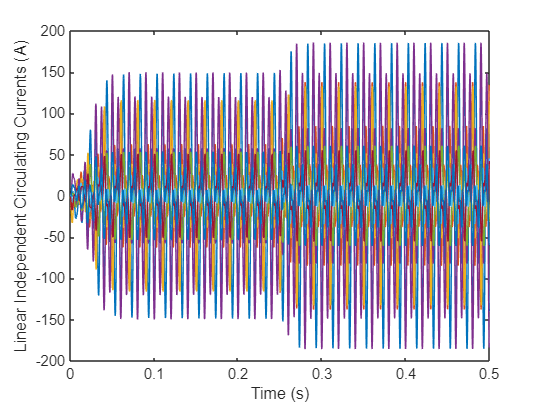

figure
plot(Ten, Ie_NN)
xlabel('Time (s)')
ylabel('Linear Independent Circulating Currents (A)')

Common mode voltage

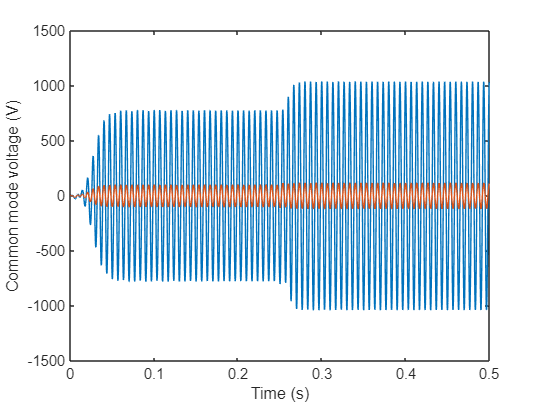

figure
plot(Ten, Von_NN)
xlabel('Time (s)')
ylabel('Common mode voltage (V)')

Controller execution time

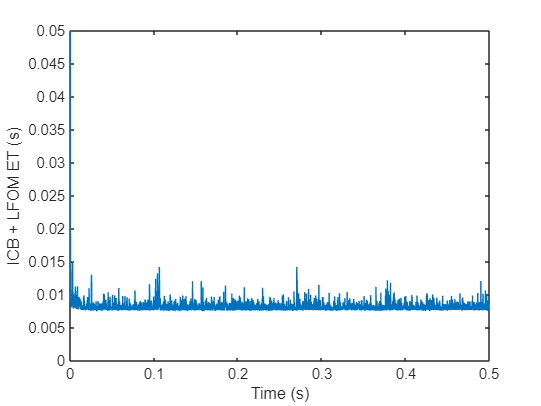

figure
plot(Tsim, Tex)
xlabel('Time (s)')
ylabel('ICB + LFOM ET (s)')
ylim([0 0.05])

## Other variables

External Currents

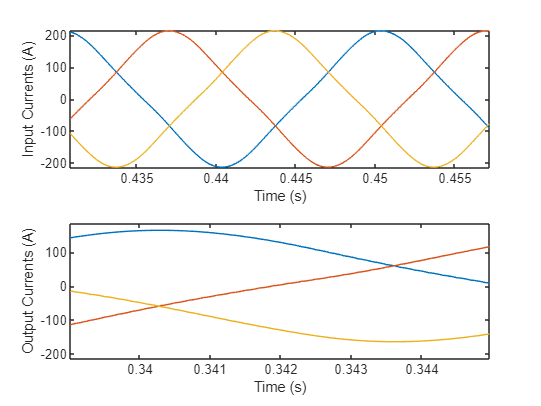

figure
subplot(2, 1, 1)
plot(Tsim, ixy(1:3, :))
xlabel('Time (s)')
ylabel('Input Currents (A)')
subplot(2, 1, 2)
plot(Tsim, ixy(4:6, :))
xlabel('Time (s)')
ylabel('Output Currents (A)')

Cluster Currents

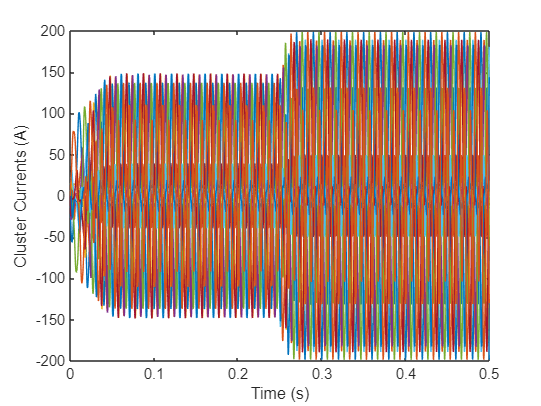

figure
plot(Tsim, is(:, 1:end-1))
xlabel('Time (s)')
ylabel('Cluster Currents (A)')

Circulating Currents

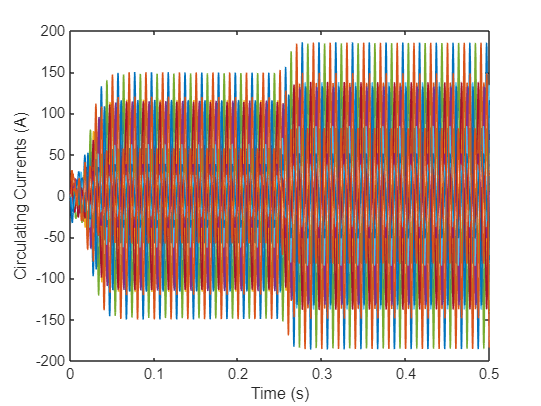

figure
plot(Tsim, iz_ref)
xlabel('Time (s)')
ylabel('Circulating Currents (A)')

Cluster and Branch Voltages

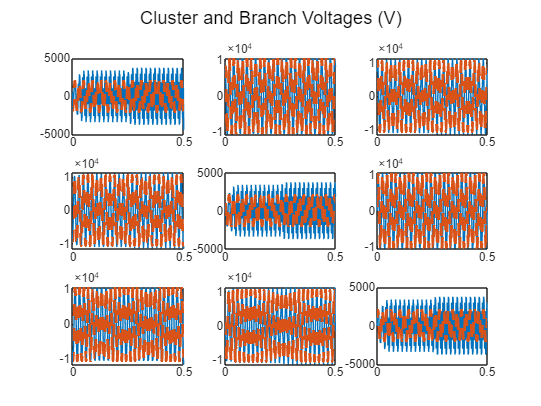

figure
subplot(ceil(m/3), 3, 1)
plot(Tsim, vs(1, :))
hold on
plot(Tsim, vB(1, :), '--', 'LineWidth', 2)
hold off
for idx = 2:m
    subplot(ceil(m/3), 3, idx)
    plot(Tsim, vs(idx, :))
    hold on
    plot(Tsim, vB(idx, :), '--', 'LineWidth', 2)
    hold off
end
sgtitle("Cluster and Branch Voltages (V)")

Mean Cluster Voltage

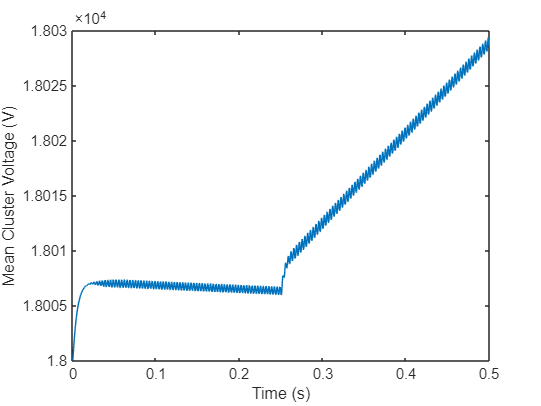

figure
plot(Tsim, vcmean)
hold on
yline(vc_ref)
xlabel('Time (s)')
ylabel('Mean Cluster Voltage (V)')

Capacitor Voltage Deviation, Capacitor Voltage Standard Deviation

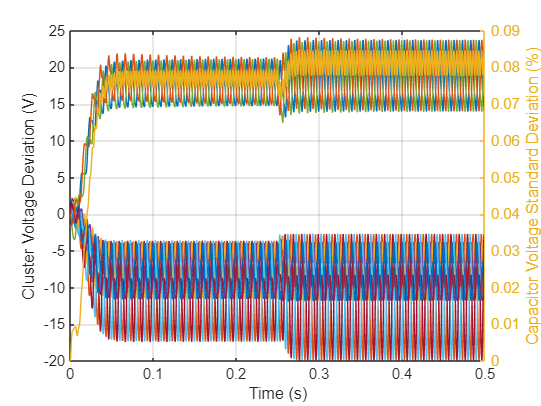

figure
plot(Tsim, vc(:, 1:end-1)-vcmean)
ylabel('Cluster Voltage Deviation (V)')

yyaxis right
vsd = 100*std((vc(:, 1:end-1)-vcmean)./vcmean, 0, 1);
plot(Tsim, vsd)
ylabel('Capacitor Voltage Standard Deviation (%)')

grid on
xlabel('Time (s)')

RMS Basic Current, Circulating Current

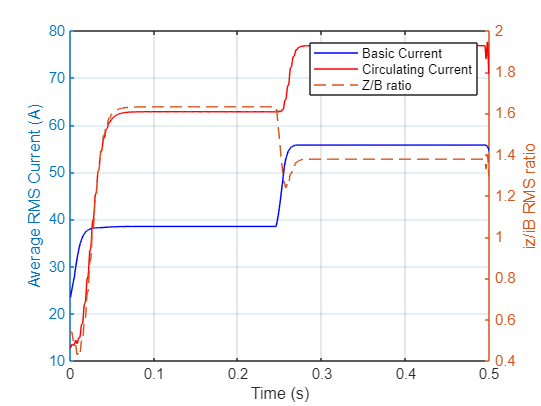

b = 500; % Window length
izrms = mean(sqrt(movmean(iz_ref.^2, b, 2)), 1);
iBrms = mean(sqrt(movmean(iB.^2, b, 2)), 1);

figure

yyaxis left
plot(Tsim, iBrms, 'LineStyle', '-', 'Color', 'b')
hold on
plot(Tsim, izrms, 'LineStyle', '-', 'Color', 'r')
hold off
ylabel('Average RMS Current (A)')

yyaxis right
plot(Tsim, izrms./iBrms, 'LineStyle', '--')

grid on
xlabel('Time (s)')
ylabel('iz/iB RMS ratio')
legend('Basic Current', 'Circulating Current', 'Z/B ratio')

Cluster Energy

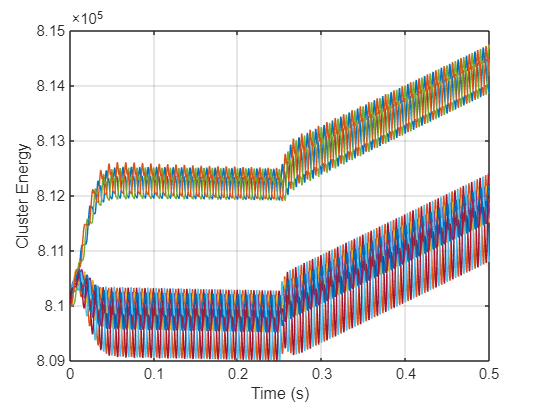

figure
plot(Tsim, Ec(:, 1:end-1))
grid on
xlabel('Time (s)')
ylabel('Cluster Energy')